# A test harness script - **blocks**

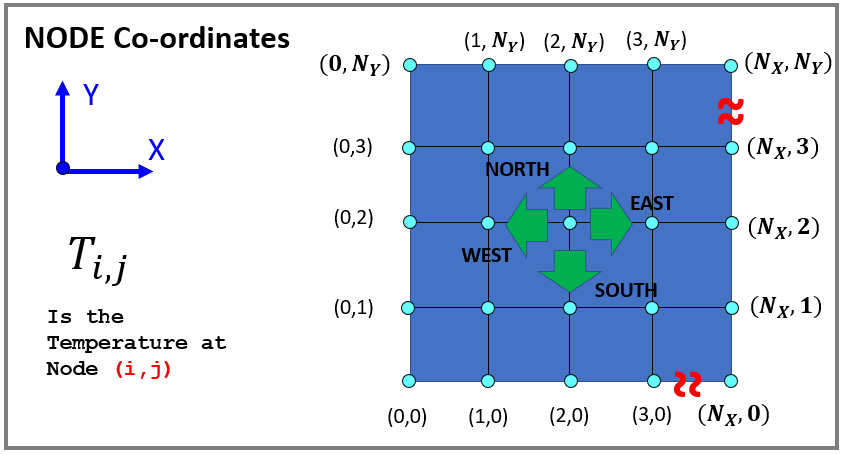

## Test the [bh_block_CLS](matlab: edit bh_block_CLS) class

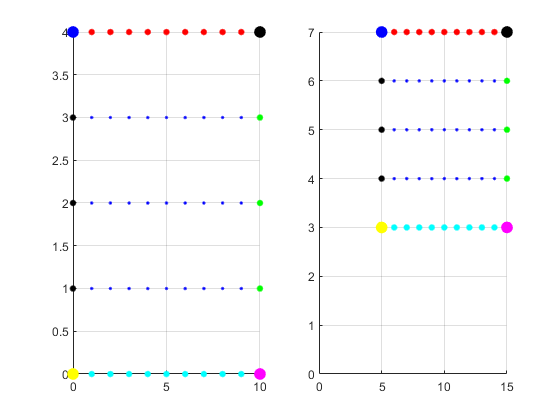

Nx       = 10;
Ny       = 4;

i_offset = 5;
j_offset = 3;

obj = bh_block_CLS(Nx, Ny,"i_offset",i_offset,"j_offset",j_offset);

figure;
    hax(1) = subplot(1,2,1);   obj.plot("Local_ij", "Parent", hax(1) );
    hax(2) = subplot(1,2,2);   obj.plot("Global_ij", "Parent", hax(2) );  

Look at the table of nodes

obj.tab

ans = 55×6 table
    i_local    j_local    i_global    j_global    is_active    node_type_blk 
    _______    _______    ________    ________    _________    ______________

       0          0           5          3          true       "BC_CORNER_SW"
       1          0           6          3          true       "BC_SOUTH"    
       2          0           7          3          true       "BC_SOUTH"    
       3          0           8          3          true       "BC_SOUTH"    
       4          0           9          3          true       "BC_SOUTH"    
       5          0          10          3          true       "BC_SOUTH"    
       6          0          11          3          true       "BC_SOUTH"    
       7          0          12          3          true       "BC_SOUTH"   

We can extract specific nodes

my_subtab = obj.get_subtable("NODES_WEST_FACE_EXCLUDING_CORNERS")

my_subtab = 3×6 table
    i_local    j_local    i_global    j_global    is_active    node_type_blk
    _______    _______    ________    ________    _________    _____________

       0          1          5           4          true         "BC_WEST"  
       0          2          5           5          true         "BC_WEST"  
       0          3          5           6          true         "BC_WEST"  


## Test the [bh_block_CLS](matlab: edit bh_block_CLS) class

Here's an example of using 3 blocks to represent the 3 different components in our House insulation problem

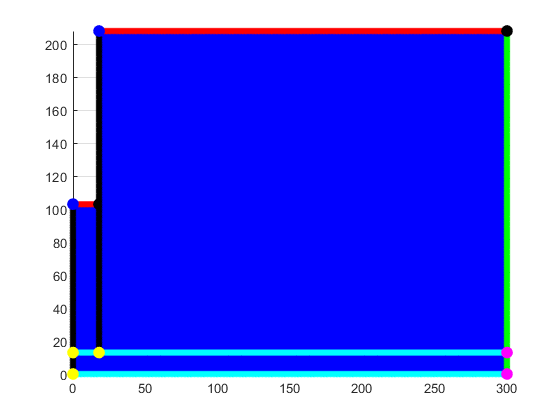

block_A = bh_block_CLS(300 ,13, "i_offset",0,  "j_offset",0);

block_B = bh_block_CLS(18,  90, "i_offset",0,  "j_offset",13);

block_C = bh_block_CLS(282, 195, "i_offset",18, "j_offset",13);


figure;
    hax = axes;
    block_A.plot("Global_ij", "Parent",hax);
    block_B.plot("Global_ij", "Parent",hax);
    block_C.plot("Global_ij", "Parent",hax);